# Final Project

## Paul Keene, Erica Lin

Dataset: Steinmetz, Zatka-Haas, Carandini & Harris 2019

## Setup

%set project directory (will need to change on different machine)
projDir = pwd;

%get session IDs and number
[sessionNames,nsesh] = getSessionNames(projDir);

%load the data from the raw files
[beh,eye] = loadData(sessionNames,nsesh,projDir);
load('sorted_data/neural/spikes.mat');

% load paths for functions
visualization_path = [pwd,'/visualize']; 
addpath(visualization_path);
analysis_path = [pwd,'/analysis']; 
addpath(analysis_path);

## Visualization

% motor neuron activity during response to left vs right vs neutral trials
raster_subject1_directional(beh, spikes)

% visual neuron activity during stimulus of high, medium, and no difference between right and left
isi_subject1_contrast(beh, spikes)

% average spike counts during stimulus times for motor and visual neurons
psth_avg_spike_count(beh, spikes)

% visualize gaze after stimulus appears
gaze_tracking() 

% visualize wheel position during trial
wheel_position()

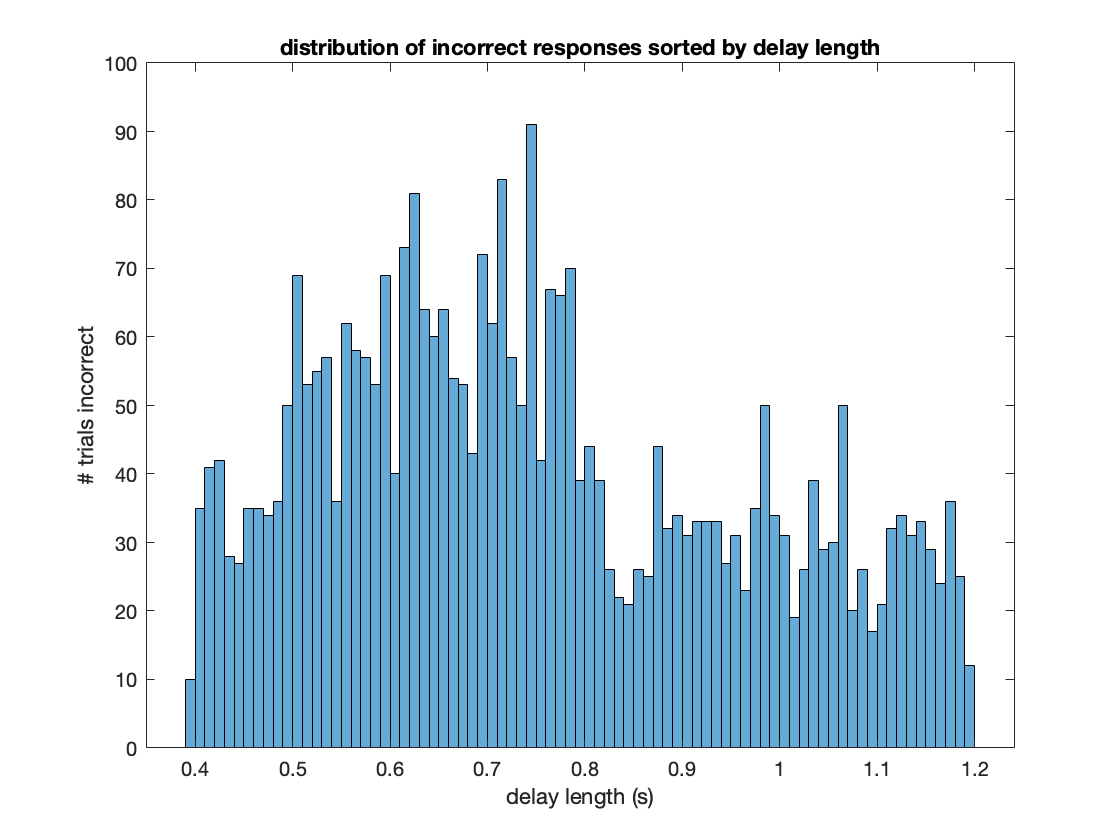

%histogram of accuracy sorted by delay interval
accuracy_v_delay()

## Analysis

% Spike train variability for MOs 50ms 
% before / after 
% stimulus / go cue / response
spike_train_variability(beh, spikes)

Find the Fano Factor of 50 ms before audio go-cue, 50 ms after audio go-cue, 50 ms before visual go-cue, and 50 ms after visual go-cue.MOs Fano Factor for spike count 50 ms before stimulus

ans = 151.8083

MOs Fano Factor for spike count 50 ms after stimulus

ans = 154.1373

MOs Fano Factor for spike count 50 ms before go cue

ans = 152.1919

MOs Fano Factor for spike count 50 ms after go cue

ans = 156.3190

MOs Fano Factor for spike count 50 ms before response

ans = 147.6806

MOs Fano Factor for spike count 50 ms after response

ans = 152.1747

Fano Factor of spike count in MOs is always higher (relatively higher spike count variability)after stimulus / go cue / response than before.
Fano Factor of spike count in MOs is lowest overall after response -- there is relatively lower spike count variability after response.